# Prep neuromaps images for CANlab tools - part 2

Purpose: Explore neuromaps PET images using CANlab tools, and create final set of maps to use in other studies

obj_masked_zscored_averaged  is the final object to use. It is stored in 

These images are part of the Neuromaps toolbox:

Hansen et al. "Mapping neurotransmitter systems to the structural and functional

organization of the human neocortex"

https://www.biorxiv.org/content/10.1101/2021.10.28.466336v2

https://www.biorxiv.org/content/10.1101/2021.10.28.466336v2.full.pdf

**The specifc images here come from Justine Hansen's repository:**

[https://github.com/netneurolab/hansen_receptors/tree/main/data/PET_nifti_images](https://github.com/netneurolab/hansen_receptors/tree/main/data/PET_nifti_images)

**Notes from Justine Hansen:**

One quick way to get access to all the receptor maps on neuromaps is to do `available_annotations(tags='receptors')`�. These are study-specific and not all of them made it into the [Hansen 2021 preprint](https://www.biorxiv.org/content/10.1101/2021.10.28.466336v2). All the images used in Hansen 2021 are also on that preprint's [github](https://github.com/netneurolab/hansen_receptors/tree/main/data/PET_nifti_images). That repo also has [supplementary table S3](https://github.com/netneurolab/hansen_receptors/tree/main/manuscript) with PET tracer name, receptor target, and links to all the papers that originally publish the data (except for a few exceptions that were shared before publication). The list of receptors that are used in the main analyses in Hansen 2021 (including those that get combined into a single receptor map post-parcellation) can be found in Table 1 in the preprint and in [this script](https://github.com/netneurolab/hansen_receptors/blob/main/code/make_receptor_matrix.py) (which also outlines how I combine some maps).

See also:

Markello et al. "neuromaps: structural and functional interpretation of brain maps"

[https://www.biorxiv.org/content/10.1101/2022.01.06.475081v1](https://www.biorxiv.org/content/10.1101/2022.01.06.475081v1)

## Load and prep maps

- You must have the file below on your path. This stores the fmri_data object with the maps.

- There are  39 images total. Some are duplicates that were averaged in some way in the preprint, weighted by sample size after z-scoring. Some images are not the metadata table (Table S3) and were removed. One image in the metadata table was not in the image set.

- Things to note: The images have different voxel sizes/spaces. They were esampled to a common MNI-space template image.  The input images have different masking applied (some have some sulci, etc. masked out), different scaling, and some (at least one) has been z-scored prior to storage in the collection.  All images have been l2-normed to put them roughly on the same scale. Metrics like cosine simlarity and correlation are most appropriate to use on these maps.

clear obj
load Hansen_2022_PET_tracer_maps obj

% take a peek at some of the meta-data
obj.metadata_table(1:5, :)


## Examine correlations among maps

- Are the correlations higher for the same tracer than across tracers?  

- Mostly...but some 5HT maps look suspicious, and a few others too, because they correlate more highly with maps of DIFFERENT neurotransmitters than with maps of the SAME neurotransmitter. 

- This may be because some maps that are highly correlated but with different tracers  come from the same study (e.g., Beliveau). The plot below suggests that for studies with multiple maps, study drives the correlation more strongly than the neurotransmitter (only really testable for the 5HT maps and DAT -- DAT looks better in this regard).

- Study-driven correlations may be related to masking, along with other variables.  We can see that the images are masked differently. For some, a tight gray-matter mask has been applied, so that medial PFC voxels and others are masked out. 

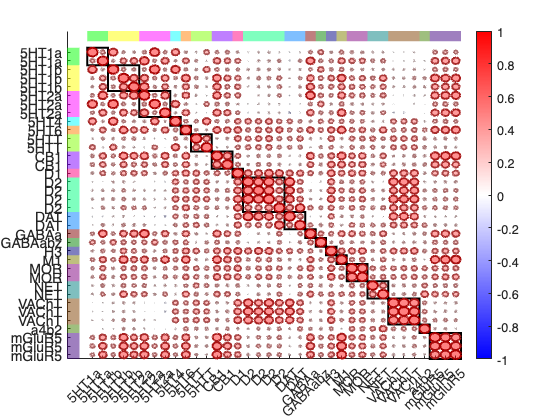

Note: Variables were re-ordered based on partitions. Reordered names saved in .var_names field.


% basic plot

Note: Variables were re-ordered based on partitions. Reordered names saved in .var_names field.


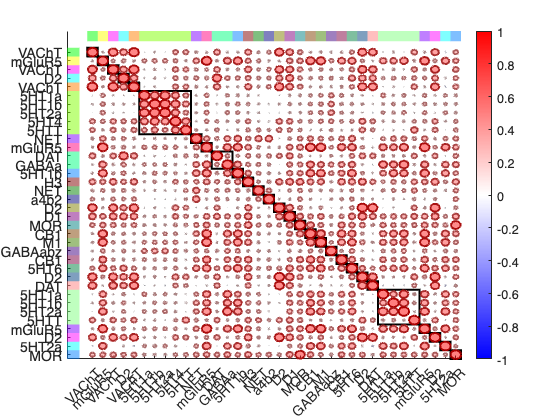

plot_correlation_matrix(obj.dat, 'var_names', obj.metadata_table.target);

% Check out with tracers annotated by color bars
% (this reorders the matrix so the integer partition codes are sequential)

[indic, nms, condf] = string2indicator(obj.metadata_table.target);

plot_correlation_matrix(obj.dat, 'var_names', obj.metadata_table.target, 'partitions', condf);

% Check out with studies annotated by color bars

t = 36×2 table
                      Var1                      Var2
    ________________________________________    ____

    {'PI: Lauri Tuominen & Synthia Guimond'}      1 
    {'PI: Pedro Rosa-Neto'                 }      2 
    {'aghourian2017molpsychiatry'          }      3 
    {'alakurtti2015jcerebbloodflowmetab'   }      4 
    {'bedard2019sleepmed'                  }      5 
    {'beliveau2017jneurosci'               }      6 
    {'beliveau2017jneurosci'               }      6 
    {'beliveau2017jneurosci'               }      6 
    {'beliveau2017jneurosci'               }      6 
    {'beliveau2017jneurosci'               }      6 
    {'ding2010synapse'                     }      7 
    {'dubois2016eurjnuclmedmolimaging'     }      8 
    {'dukart2018scirep'                    }      9 
    {'dukart2018scirep'                    }      9 
    {'gallezot2010jcerebbloodflowmetab'    }     10 
    {'gallezot2

% (this reorders the matrix so the integer partition codes are sequential)

[~, ~, study_vector] = string2indicator(obj.metadata_table.primary_reference);
plot_correlation_matrix(obj.dat, 'var_names', obj.metadata_table.target, 'partitions', study_vector);

[study_vector_sorted, indx] = sort(study_vector);
t = table(obj.metadata_table.primary_reference(indx), study_vector(indx))


### IMPORTANT THINGS TO CONSIDER - MISSING VOXELS

- The "devil is in the details"!

- These correlations are list-wise deleted for missing data across all voxels (only across voxels with valid values for one or more images). This way, voxels missing and coded as 0 in one image may be treated (wrongly) as numeric data. But one could also do this list-wise deleted with missing data for *any* map deleted. Or pair-wise, requiring valid data for both members of each pair of maps. 

- Arguably, it may make sense to z-score maps *omitting all 0-valued [which is not a valid value] voxels first. That way, with zeros in the image, they don't influence the correlation (they are at the mean value for the map). The following lines of code verify this.

- Some images have near-zero but not exactly zero values, which means they will contribute to correlations even after z-scoring. For example, check out image 32. You can see that the values around the edge of the images have been masked out, but their values are not zero, but -0.00023642.  So they show up in the coverage map as being valid voxels. This requires special adjustment to the images because otherwise they will be treated as numeric data in z-scoring and image scaling operations (like l2-norming).

- Another clue is that binding values below 0 are *not* plausible/valid, unless the image has been z-scored, which does not appear to be the case here.

- **This could be due to interpolation/resampling errors when creating the image set**.

obj1 = get_wh_image(obj, 32);
plot(obj1)

ans = 36×3 table
     target                 tracer               Indx
    _________    ____________________________    ____

    {'5HT1a'}    {'[11C]CUMI-101'           }      1 
    {'5HT1a'}    {'[carbonyl-11C]WAY-100635'}      2 
    {'5HT1b'}    {'[11C]AZ10419369'         }      3 
    {'5HT1b'}    {'[11C]P943'               }      4 
    {'5HT1b'}    {'[11C]P943'               }      5 
    {'5HT2a'}    {'[18F]ALTANSERIN'         }      6 
    {'5HT2a'}    {'[11C]CIMBI-36'           }      7 
    {'5HT2a'}    {'[11C]MDL100907'          }      8 
    {'5HT4' }    {'[11C]SB207145'           }      9 
    {'5HT6' }    {'[11C]GSK215083'          }     10 
    {'5HTT' }    {'[11C]DASB'               }     11 
    {'5HTT' }    {'[11C]DASB'               }     12 
    {'a4b2' }    {'[18F]FLUBATINE'          }     13 
    {'CB1'  }    {'[18F]FMPEP-D2'           }     14 
    {'CB1'  }   

dd = descriptives(obj1, 'plotcoverage');

plot(obj1, 'montages');
    
    name = sprintf('%s %s %3.0f', obj1.metadata_table.target{1}, obj1.metadata_table.primary_reference{1}, 32);
    
    set(gcf, 'Tag', name, 'Name', name);
    title(name);
    drawnow

To adjust this, we need to manually set these to zero:

Try using the mode, and/or values. This may work for all the images? We have to check it doesn't do wonky things for some images. Also, some may not have a single modal value with many voxels if it is not masked improperly, so


mymode = mode(obj1.dat);
% obj1.dat(obj1.dat < 0) = 0;
obj1.dat(obj1.dat == mymode) = 0;


ans = 1×16 table
                    target                                             tracer                                                  scanner                           N     n_male    n_female    age_years    sd_age                 parameter                         modelling_method                                 reference_region                          scan_length_min         modeling_notes                                                    primary_reference                                                        see_also                                                                         contact                                                             
    ____________________________________

figure; histogram(obj1);


plot(obj1)
dd = descriptives(obj1, 'plotcoverage');

Now the coverage looks as intended, with ventricles masked out. Now when we z-score, we won't create artificial negative values in these out-of-brain voxels. NOTE: you need to check that the code you are using to z-score images excludes missing values! (0 or NaN). The fmri_data.rescale function did not do this, and I adjusted it so that it does!

### Loop through and adjust zeros based on mode

obj_adj = obj;

ans = 1×16 table
                      target                                               tracer                                            scanner                    N     n_male    n_female    age_years    sd_age                 parameter                            modelling_method                                           reference_region                                  scan_length_min         modeling_notes                                                    primary_reference                                                        see_also                                                     contact                                          
    __________________________________________    


do_adjust = true;

for i = 1:size(obj.dat, 2)
    
    

ans = 1×16 table
          target                         tracer                          scanner           N     n_male    n_female    age_years    sd_age          parameter              modelling_method                reference_region             scan_length_min    modeling_notes                                 primary_reference                                                                                                                                                                         see_also                                                                                                                                                                                            contact                        

    obj1 = get_wh_image(obj, i);
    
    mymode = mode(obj1.dat);
    
    ismissing = obj1.dat == 0 | isnan(obj1.dat);
    mymode_nonzero = mode(obj1.dat(~ismissing));

ans = 1×16 table
             target                          tracer                        scanner            N     n_male    n_female    age_years    sd_age          parameter               modelling_method                 reference_region             scan_length_min                                                               modeling_notes                                                                                       primary_reference                                                                                                                                                                                         see_also                                                                                                      

    
    num_vox_at_mode(i) = sum(obj1.dat == mymode);
    num_vox_at_mode_nonzero(i) = sum(obj1.dat == mymode_nonzero);
    
    
    fprintf('Image %3.0f  mode = %3.4f mode_excluding_0 = %3.4f vox at mode: %3.0f vox at mode nonzero: %3.0f\n', i, mymode, mymode_nonzero, num_vox_at_mode(i), num_vox_at_mode_nonzero(i));

ans = 30×3 table
             target                          tracer                 Indx
    ________________________    ________________________________    ____

    {'5HT1a'               }    {'[11C]CUMI-101'               }      1 
    {'5HT1a'               }    {'[carbonyl-11C]WAY-100635'    }      2 
    {'5HT1b'               }    {'[11C]AZ10419369'             }      3 
    {'Average: 5HT1b_5HT1b'}    {'Average: [11C]P943_[11C]P943'}      4 
    {'5HT2a'               }    {'[18F]ALTANSERIN'             }      5 
    {'5HT2a'               }    {'[11C]CIMBI-36'               }      6 
    {'5HT2a'               }    {'[11C]MDL100907'              }      7 
    {'5HT4'                }    {'[11C]SB207145'               }      8 
    {'5HT6'                }    {'[11C]GSK215083'              }      9 
    {'5HTT'                }    {'[11C]DASB'                   }     10 
    

    
    if do_adjust

ans = 4×16 table
                      target                                               tracer                                                    scanner                            N     n_male    n_female    age_years    sd_age                 parameter                            modelling_method                                           reference_region                                  scan_length_min                                                               modeling_notes                                                                                                          primary_reference                                                                                                                                                        

        
        if num_vox_at_mode(i) > 1000
            
            obj1.dat(obj1.dat == mymode) = 0;
            
        end
        
        if num_vox_at_mode_nonzero(i) > 1000
            
            obj1.dat(obj1.dat == mymode_nonzero) = 0;
            
        end
        
        % Update data in object
        obj_adj.dat(:, i) = obj1.dat;

Note: Variables were re-ordered based on partitions. Reordered names saved in .var_names field.


    end
    
    plot(obj1, 'montages');
    
    name = sprintf('%s %s %3.0f', obj1.metadata_table.target{1}, obj1.metadata_table.primary_reference{1}, i);
    
    set(gcf, 'Tag', name, 'Name', name);
    title(name);
    drawnow

Note: Variables were re-ordered based on partitions. Reordered names saved in .var_names field.


    
end


t = 30×2 table
                                                      Var1                                                      Var2
    ________________________________________________________________________________________________________    ____

    {'Average: Average: PI: Lauri Tuominen & Synthia Guimond_bedard2019sleepmed_aghourian2017molpsychiatry'}      1 
    {'Average: Average: PI: Pedro Rosa-Neto_dubois2016eurjnuclmedmolimaging_smart2019eurjnuclmedmolimaging'}      2 
    {'Average: gallezot2010jcerebbloodflowmetab_savli2012neuroimage'                                       }      3 
    {'Average: smith2017jcerebbloodflowmetab_sandiego2015jcerebbloodflowmetab'                             }      4 
    {'alakurtti2015jcerebbloodflowmetab'                                                                   }      5 
    {'beliveau2017jneurosci'                                                                     

% Check the object
plot(obj_adj);

Direct calls to spm_defauts are deprecated.
Please use spm('Defaults',modality) or spm_get_defaults instead.
Defaults settings have been modified by file(s):
  /Users/torwager/Dropbox (Dartmouth College)/Matlab_code_external/spm12/spm_my_defaults.m
Modified fields: stats 


sampleto = '/Users/torwager/Documents/GitHub/CanlabCore/CanlabCore/Sample_datasets/Wager_et_al_2008_Neuron_EmotionReg/Wager_2008_emo_reg_vs_look_neg_contrast_images.nii'

Defaults settings have been modified by file(s):
  /Users/torwager/Dropbox (Dartmouth College)/Matlab_code_external/spm12/spm_my_defaults.m
Modified fields: stats 
Loaded images:
/Users/torwager/Documents/GitHub/CanlabCore/CanlabCore/Sample_datasets/Wager_et_al_2008_Neuron_EmotionReg/Wager_2008_emo_reg_vs_look_neg_contrast_images.nii
/Users/torwager/Documents/GitHub/CanlabCore/CanlabCore/Sample_datasets/Wager_et_al_2008_Neuron_EmotionReg/Wager_2008_emo_reg_vs_look_neg_contrast_images.nii
/Users/torwager/Documents/GitHub/CanlabCore/CanlabCore/Sample_datasets/Wager_et_al_2008_Neuron_EmotionReg/Wager_2008_emo_reg_vs_look_neg_contrast_images.nii
/Users/torwager/Documents/GitHub/CanlabCore/CanlabCore/Sample_datasets/Wager_et_al_2008_Neuron_EmotionReg/Wager_2008_emo_reg_vs_look_neg_contrast_images.nii
/Users/torwager/Documents/GitHub/CanlabCore/CanlabCore/Sample_datasets/Wager_et_al_2008_Neuron_EmotionReg/Wager_2008_emo_reg_vs_look_neg_contrast_images.nii
/Users/torwager/Documents/GitHub/Can


dd = descriptives(obj_adj, 'plotcoverage');

Number of zero or NaN values within weight mask, by input image:
  0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0  12   0   0   0   0   0   0   0   0   0   0 
Table of correlations Group:1
--------------------------------------
T-test on raw similarity measured by cosine
 	R_avg	T	P	sig	
5HT1a	0.0139	1.1096	0.2763	0.0000	
5HT1a	0.0506	3.0645	0.0047	1.0000	
5HT1b	0.0353	2.0256	0.0521	0.0000	
5HT1b	0.0997	4.6934	0.0001	1.0000	
5HT2a	0.0676	4.4843	0.0001	1.0000	
5HT2a	0.0290	1.7324	0.0938	0.0000	
5HT2a	0.0800	3.8620	0.0006	1.0000	
5HT4	0.0160	1.5960	0.1213	0.0000	
5HT6	0.0696	3.4737	0.0016	1.0000	
5HTT	-0.0303	-2.0597	0.0485	1.0000	
5HTT	-0.0032	-0.3253	0.7473	0.0000	
a4b2	0.0179	1.5702	0.1272	0.0000	
CB1	0.1251	4.9025	0.0000	1.0000	
CB1	0.0876	4.8759	0.0000	1.0000	
D1	0.0151	1.1787	0.2481	0.0000	
D2	-0.0082	-0.6852	0.4986

Look at an image with lots of negative values. It may have been Z-scored ahead of time.

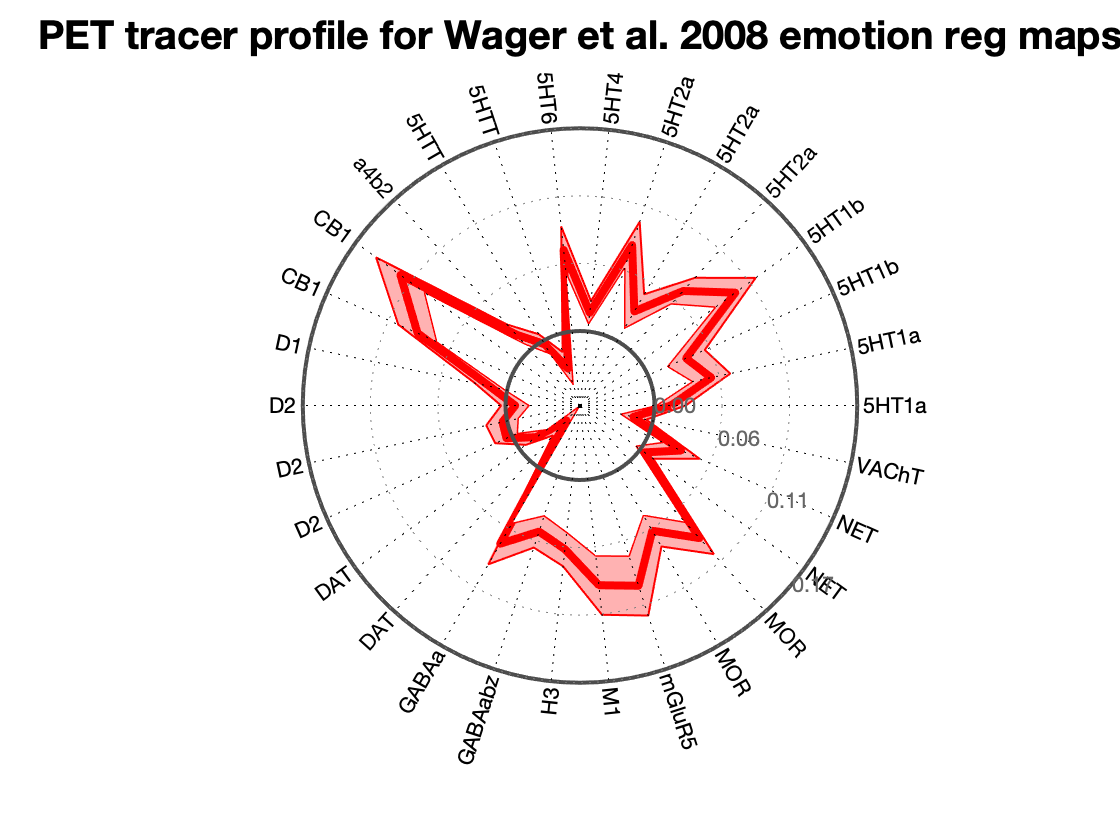

obj1 = get_wh_image(obj, 32);

plot(obj1);
obj1 = remove_empty(obj1);
mean(obj1.dat)

### Replace negative values with 0 (exclude voxels) for selected images

Some images still have negative values in ventricles that are distinct from those masked out above.

% check 2 3 7 9 24 32

Number of zero or NaN values within weight mask, by input image:
  0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0  43   0   1   0   0   0   0   0   0   0   0 
Number of zero or NaN values within weight mask, by input image:
  0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0  43   0   1   0   0   0   0   0   0   0   0 
Number of zero or NaN values within weight mask, by input image:
  0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0  43   0   1   0   0   0   0   0   0   0   0 

% some (2 3 at least) seem to have neg values in plot but they are actually 0 
s = sum(obj_adj.dat < 0)
wh = find(s)
s(wh)

obj1 = get_wh_image(obj_adj, 2);
dd = descriptives(obj1, 'plotcoverage');

Loading /Users/torwager/Dropbox (Dartmouth College)/COURSES/Courses_Dartmouth/2021_3_Spring_fMRI_Class/PSYC60_Shared_resources_for_students/datasets/kragel_2018_nat_neurosci_270_subjects_test_images.mat
Loaded images:
ThermalPain1
ThermalPain1
ThermalPain1
ThermalPain1
ThermalPain1
ThermalPain1
ThermalPain1
ThermalPain1
ThermalPain1
ThermalPain1
ThermalPain1
ThermalPain1
ThermalPain1
ThermalPain1
ThermalPain1
ThermalPain2
ThermalPain2
ThermalPain2
ThermalPain2
ThermalPain2
ThermalPain2
ThermalPain2
ThermalPain2
ThermalPain2
ThermalPain2
ThermalPain2
ThermalPain2
ThermalPain2
ThermalPain2
ThermalPain2
VisceralPain1
VisceralPain1
VisceralPain1
VisceralPain1
VisceralPain1
VisceralPain1
VisceralPain1
VisceralPain1
VisceralPain1
VisceralPain1
VisceralPain1
VisceralPain1
VisceralPain1
VisceralPain1
VisceralPain1
VisceralPain2
VisceralPain2
VisceralPain2
VisceralPain2
VisceralPain2
VisceralPain2
VisceralPain2
VisceralPain2
VisceralPain2
VisceralPain2
VisceralPain2
VisceralPain2
VisceralPain2


plot(obj1, 'montages');
colorbar




obj1 = get_wh_image(obj_adj, 3);
dd = descriptives(obj1, 'plotcoverage');
plot(obj1, 'montages');
colorbar

obj1 = get_wh_image(obj_adj, wh(1));
obj1.dat(obj1.dat < 0) = 10;
plot(obj1, 'montages');

obj1 = get_wh_image(obj_adj, wh(2));
obj1.dat(obj1.dat < 0) = 10;
plot(obj1, 'montages');


% wh(1, 2, 4, 5, 6, 8, 9) seem to have neg values around edges of brain, like a masking
% issue
% wh(7) i can't tell, and wh(3) and wh(10) seems to be valid brain areas (maybe map
% was centered earlier? so don't exclude those voxels)

for i = [1 2 4 5 6 8 9]
    
    obj1 = get_wh_image(obj_adj, wh(i));
    obj1.dat(obj1.dat < 0) = 0;
    
    obj_adj.dat(:, wh(i)) = obj1.dat;
    
end

s = sum(obj_adj.dat < 0)
wh = find(s)
s(wh)


**Mask all with common gray matter mask to increase uniformity**

obj_adj = apply_mask(obj_adj,  which('gray_matter_mask.nii'));

plot(obj_adj)
dd = descriptives(obj_adj, 'plotcoverage');


### Rescale (z-score) within non-empty areas of each image

Z-score because some (at least 1) image is already z-scored from the start.  This is the safest/most viable option for the whole set.

obj_adj = rescale(obj_adj, 'zscoreimages');
plot(obj_adj)


### Show coverage for each individually

for i = 1:size(obj_adj.dat, 2)
    
    obj1 = get_wh_image(obj_adj, i);
    plot(obj1, 'montages');
    
    name = sprintf('%s %s %3.0f', obj1.metadata_table.target{1}, obj1.metadata_table.primary_reference{1}, i);
    
    set(gcf, 'Tag', name, 'Name', name);
    title(name);
    drawnow
    
end


### %%

Look at an image with masking that may still be problematic?

Note: This looks funny in the montage because of how 0s are represented in the montage (dark blue)

obj1 = get_wh_image(obj_adj, 13);
plot(obj1, 'montages'); colorbar
figure; 
histogram(obj1)

mymode = mode(obj1.dat)
    
    ismissing = obj1.dat == 0 | isnan(obj1.dat);
    mymode_nonzero = mode(obj1.dat(~ismissing))
    
    nv = sum(obj1.dat == mymode)
    nvnz = sum(obj1.dat == mymode_nonzero);
    
    ob1.dat(obj1.dat == nvnz) = 0;
    
    % Check that it worked
    
    ismissing = obj1.dat == 0 | isnan(obj1.dat);
    mymode_nonzero2 = mode(obj1.dat(~ismissing))
    nvnz2 = sum(obj1.dat == mymode_nonzero2)
    
    plot(obj1, 'montages'); colorbar
figure; 
histogram(obj1)


### Save

Note: Objects may be over 100 MB, so will be too big for Github. Be careful!  Use space-saving strategies below.


obj_masked_zscored = obj_adj;

obj_masked_zscored = remove_empty(obj_masked_zscored);
obj_masked_zscored = enforce_variable_types(obj_masked_zscored);

obj = remove_empty(obj);
obj = enforce_variable_types(obj);

save Hansen_2022_PET_tracer_maps obj

save Hansen_2022_PET_tracer_maps_masked obj_masked_zscored



## Re-Examine correlations among maps

- Are the correlations higher for the same tracer than across tracers?  

- After adjustments, correlations tend to be higher within transmitter type across studies, and lower within stiudy across transmitters. This is preferred, and suggests that adjustments have helped.

% Check out with tracers annotated by color bars
% (this reorders the matrix so the integer partition codes are sequential)

[indic, nms, condf] = string2indicator(obj_masked_zscored.metadata_table.target);
plot_correlation_matrix(obj_masked_zscored.dat, 'var_names', obj_masked_zscored.metadata_table.target, 'partitions', condf);

% Check out with studies annotated by color bars
% (this reorders the matrix so the integer partition codes are sequential)

[~, ~, study_vector] = string2indicator(obj_masked_zscored.metadata_table.primary_reference);
plot_correlation_matrix(obj_masked_zscored.dat, 'var_names', obj_masked_zscored.metadata_table.target, 'partitions', study_vector);

[study_vector_sorted, indx] = sort(study_vector);
t = table(obj_masked_zscored.metadata_table.primary_reference(indx), study_vector(indx))

% saveas(gcf, 'Hansen_PET_maps_intercorrelations.png');
% saveas(gcf, 'Hansen_PET_maps_intercorrelations.fig');

## Combine maps

From Justine Hansen's script:

https://github.com/netneurolab/hansen_receptors/blob/main/code/make_receptor_matrix.py

`# weighted average of 5HT1B p943`

`receptor_data``[:, ``1``] ``=`` (``zscore``(``r``[:, ``1``])``*``22` `+` `zscore``(``r``[:, ``2``])``*``65``) ``/`` (``22``+``65``)`

`# weighted average of D2 flb457`

`receptor_data``[:, ``9``] ``=`` (``zscore``(``r``[:, ``10``])``*``37` `+` `zscore``(``r``[:, ``11``])``*``55``) ``/`` (``37``+``55``)`

`# weighted average of mGluR5 ABP688`

`receptor_data``[:, ``14``] ``=`` (``zscore``(``r``[:, ``16``])``*``22` `+` `zscore``(``r``[:, ``17``])``*``28` `+` `zscore``(``r``[:, ``18``])``*``73``) ``/`` (``22``+``28``+``73``)`

`# weighted average of VAChT FEOBV`

`receptor_data``[:, ``18``] ``=`` (``zscore``(``r``[:, ``22``])``*``3` `+` `zscore``(``r``[:, ``23``])``*``4` `+` `zscore``(``r``[:, ``24``]) ``+` `zscore``(``r``[:, ``25``])) ``/`` \`

`                       (``3``+``4``+``5``+``18``)`

`NOTE:  One of the VAChT studies was not complete in both file and metadata (Spreng I think) and so is not included here.`

t = obj_masked_zscored.metadata_table(:, 1:2);
addvars(t, [1:size(t, 1)]', 'NewVariableNames', 'Indx')

obj_masked_zscored_averaged = obj_masked_zscored;

% Note: this will combine rows so we need to do in reverse order from
% latest to earliest so we don't have to adjust indices

% Note: If a map does not have valid data, use ONLY the map with valid data
% for that voxel. (done in the function)

% weighted average of VAChT FEOBV
obj_masked_zscored_averaged = image_object_weighted_average(obj_masked_zscored_averaged, 34, 35);
obj_masked_zscored_averaged = image_object_weighted_average(obj_masked_zscored_averaged, 34, 35); % adjust because old 36 is now 35

obj_masked_zscored_averaged.metadata_table(34, :)

% weighted average of mGluR5 ABP688

obj_masked_zscored_averaged = image_object_weighted_average(obj_masked_zscored_averaged, 27, 28);
obj_masked_zscored_averaged = image_object_weighted_average(obj_masked_zscored_averaged, 27, 28); % adjust because old 29 is now 28

obj_masked_zscored_averaged.metadata_table(27, :)

% weighted average of D2 flb457

obj_masked_zscored_averaged = image_object_weighted_average(obj_masked_zscored_averaged, 18, 19);

obj_masked_zscored_averaged.metadata_table(18, :)

% weighted average of 5HT1B p943

obj_masked_zscored_averaged = image_object_weighted_average(obj_masked_zscored_averaged, 4, 5);

obj_masked_zscored_averaged.metadata_table(4, :)


% Now just refine the transmitter labels we combined so that they're not too long as figure labels

t = obj_masked_zscored_averaged.metadata_table(:, 1:2);
addvars(t, [1:size(t, 1)]', 'NewVariableNames', 'Indx')

obj_masked_zscored_averaged.metadata_table([4 17 25 30] , :)

obj_masked_zscored_averaged.metadata_table.target{4} = '5HT1b';
obj_masked_zscored_averaged.metadata_table.target{17} = 'D2';
obj_masked_zscored_averaged.metadata_table.target{25} = 'mGluR5';
obj_masked_zscored_averaged.metadata_table.target{30} = 'VAChT';


## Re-Examine correlations among maps

- Are the correlations higher for the same tracer than across tracers?  

- After adjustments, correlations tend to be higher within transmitter type across studies, and lower within stiudy across transmitters. This is preferred, and suggests that adjustments have helped.

% Check out with tracers annotated by color bars
% (this reorders the matrix so the integer partition codes are sequential)

[indic, nms, condf] = string2indicator(obj_masked_zscored_averaged.metadata_table.target);
plot_correlation_matrix(obj_masked_zscored_averaged.dat, 'var_names', obj_masked_zscored_averaged.metadata_table.target, 'partitions', condf);

saveas(gcf, 'Hansen_PET_maps_combined_intercorrelations.png');
saveas(gcf, 'Hansen_PET_maps_combined_intercorrelations.fig');

% Check out with studies annotated by color bars
% (this reorders the matrix so the integer partition codes are sequential)

[~, ~, study_vector] = string2indicator(obj_masked_zscored_averaged.metadata_table.primary_reference);
plot_correlation_matrix(obj_masked_zscored_averaged.dat, 'var_names', obj_masked_zscored_averaged.metadata_table.target, 'partitions', study_vector);

[study_vector_sorted, indx] = sort(study_vector);
t = table(obj_masked_zscored_averaged.metadata_table.primary_reference(indx), study_vector(indx))


## Save


save Hansen_2022_PET_tracer_maps_masked_combined obj_masked_zscored_averaged


## Summary

- 39 original images. some dup transmitters. 

- Some are masked differently than others (e.g., gray matter mask applied) and scaled differently (e.g., Z-score, or different intensity scale). This will affect correlations among maps, because different maps have different voxels with valid values. Some missing values seemed to be coded with numeric non-zero values, which will also affect correlations.  

- Cleanup steps: (1) identified areas likely masked out with uniform (but non-zero) values and excluded voxels study-wise.  (2)  applied a uniform gray matter mask (a custom mask created to including brainstem/cerebellum etc.), (3) applied uniform scaling (z-scoring) within valid in-mask voxels within each study.

- These steps improved consistency across maps of the same neurotransmitter type:  Correlations tend to be higher within transmitter type across studies, and lower within stiudy across transmitters. This is preferred, and suggests that adjustments have helped.

- Combined maps with the same transmitter + tracer, as per Hansen, using sample size-weighted average.  Tracked this in history and adjusted meta-data accordingly.

- obj_masked_zscored_averaged  is the final object to use.

### Notes on neurotransmitters

- Some tracers are less familiar.  A few notes are below.

**NET: Norepinephrine transporter**.  [Decreased norepinephrine transporter availability in obesity: positron emission tomography imaging with (S, S)-[11C] O-methylreboxetine](https://www.sciencedirect.com/science/article/pii/S1053811913010148) …, [R Sinha](https://scholar.google.com/citations?user=6hFblgwAAAAJ&hl=en&oi=sra), [YS Ding](https://scholar.google.com/citations?user=xfFTPBwAAAAJ&hl=en&oi=sra), [RE Carson](https://scholar.google.com/citations?user=FHwJqMAAAAAJ&hl=en&oi=sra), **A** Neumeister - **Neuroimage**, **2014**

**mGlur5: Metabotropic glutamate receptor subtype 5**.  [Human PET studies of metabotropic glutamate receptor subtype 5 with **11C**-**ABP688**](https://jnm.snmjournals.org/content/48/2/247.short)**. **SM Ametamey, [V Treyer](https://scholar.google.com/citations?user=fB4CjRYAAAAJ&hl=en&oi=sra), [J Streffer](https://scholar.google.com/citations?user=JbqppsAAAAAJ&hl=en&oi=sra)… - Journal of Nuclear …, 2007 - Soc Nuclear Med

**VAchT: Vesicular acetycholine transporter.  [HTML]** [Brain cholinergic alterations in idiopathic REM sleep behaviour disorder: a PET imaging study with **18F**-**FEOBV**](https://www.sciencedirect.com/science/article/pii/S138994571830618X)**. **[MA Bedard](https://scholar.google.com/citations?user=p8tCKlkAAAAJ&hl=en&oi=sra), M Aghourian, C Legault-Denis… - Sleep medicine, 2019

**H3: Histamine receptor type 3**.  [Evaluation of **11C**-**GSK189254** as a novel radioligand for the H3 receptor in humans using PET](https://jnm.snmjournals.org/content/51/7/1021.short). S Ashworth, [EA Rabiner](https://scholar.google.com/citations?user=TjuRG6sAAAAJ&hl=en&oi=sra), [RN Gunn](https://scholar.google.com/citations?user=gIOPQusAAAAJ&hl=en&oi=sra)… - Journal of Nuclear …, 2010 - Soc Nuclear Med

**M1: Acetylcholine muscarinic receptor type 1**.  [First-in-human assessment of **11C**-**LSN3172176**, an M1 muscarinic acetylcholine receptor PET radiotracer](https://jnm.snmjournals.org/content/62/4/553.abstract). [M Naganawa](https://scholar.google.com/citations?user=8WdWsoEAAAAJ&hl=en&oi=sra), [N Nabulsi](https://scholar.google.com/citations?user=FBCX9CsAAAAJ&hl=en&oi=sra), [S Henry](https://scholar.google.com/citations?user=VvXMni4AAAAJ&hl=en&oi=sra)… - Journal of Nuclear …, 2021 - Soc Nuclear Med

### Test on emotion regulation dataset

test_imgs = load_image_set('emotionreg');

stats = image_similarity_plot(test_imgs, 'mapset', obj_masked_zscored_averaged, 'cosine_similarity', 'bicolor', 'networknames', obj_masked_zscored_averaged.metadata_table.target, 'plotstyle', 'polar', 'average');

title('PET tracer profile for Wager et al. 2008 emotion reg maps');


Compare with original version of maps

stats_noncleaned = image_similarity_plot(test_imgs, 'mapset', obj, 'cosine_similarity', 'bicolor', 'networknames', obj.metadata_table.target, 'plotstyle', 'polar', 'average');

title('PET tracer profile for Wager et al. 2008 - before PET map cleanup');


% Prepare maps

kragel = load_image_set('kragel270');

ispain = strcmp(kragel.metadata_table.Domain, 'Pain');
iscog = strcmp(kragel.metadata_table.Domain, 'Cog_control');
isemo = strcmp(kragel.metadata_table.Domain, 'Neg_Emotion');

pain = get_wh_image(kragel, ispain);
cog = get_wh_image(kragel, iscog);
emo = get_wh_image(kragel, isemo);


## Plot polar plots of similarity with PET binding maps for each domain

- Stats tables are saved in stats_* objects

- These tables include stats on which individual PET maps are associated with the test images (e.g., here, significantly associated across participants, treating participant as a random effect 

- stats_pain.r = spatial similarity scores for PET maps x data images


stats_pain = image_similarity_plot(pain, 'mapset', obj_masked_zscored_averaged, 'cosine_similarity', 'bicolor', 'networknames', obj_masked_zscored_averaged.metadata_table.target, 'plotstyle', 'polar', 'average');
set(gcf, 'Tag', 'pain', 'Name', 'pain')

stats_cog = image_similarity_plot(cog, 'mapset', obj_masked_zscored_averaged, 'cosine_similarity', 'bicolor', 'networknames', obj_masked_zscored_averaged.metadata_table.target, 'plotstyle', 'polar', 'average', 'colors', {[0 0 1]});
set(gcf, 'Tag', 'cog', 'Name', 'cog')

stats_emo = image_similarity_plot(emo, 'mapset', obj_masked_zscored_averaged, 'cosine_similarity', 'bicolor', 'networknames', obj_masked_zscored_averaged.metadata_table.target, 'plotstyle', 'polar', 'average', 'colors', {[.2 1 .2]});
set(gcf, 'Tag', 'emo', 'Name', 'emo')


## Analyze differences in PET binding profiles across domains

- The previous analyses tell us about which individual associations are significant, but not about whether the PET binding profiles are reliabiy different across domains.

- We can address this with two analyses:

- **Multivariate LDA analysis**: Are the domains distinguishable based on PET association profiles? 

- Here, features are PET maps and classes to be distinguished are domains. Each participant map belongs to one domain.  LDA will yield up to two discriminant functions that best separate the classes.

- Cross-validated linear discriminant analysis (LDA) can address this. Cross-validation should leave out equal members of each class (domain).  

- Other analyses that could address this are: QDA, multi-class SVM, logistic regression-based discriminant analyses, KNN, or other classifiers. 

- Useful visualizations include: (a) A cross-validated confusion matrix, and (b) a t-SNE plot of domains

- **Feature analysis**: which PET tracers best distinguish domains (i.e., are selectively associated with domains)?

- It is of interest to know which PET maps best differentiate among the domains.  These are the most informative.  A common analysis in genomics identifies the genes that best discriminate across functional groups. We perform the same analysis here, but with PET maps as features.

- the analysis here analyzes each feature separately.  For each feature, we need a metric for how reliable the differences are between domains on that feature.  We need to consider the variability within domain as well as the variability across domains.  This is what LDA does: It calculates the ratio of between-class to within-class variance, and maximizes that.  Here, we can do LDA with only a single feature.  

- An alternative to this is to identify a set of features that jointly best discriminate among classes. This would be accomplished using cross-validated regularization/shrinkage (cvshrink).

Matlab functions for these include **classify**, **crossval**, **predict**, **compact**, **cvshrink**, **fitcdiscr**, **makecdiscr**, **templateDiscriminant**, and more in the Stats and ML toolbox. These use object classes like the **ClassificationDiscriminant** class. 

CLASS = classify(SAMPLE,TRAINING,GROUP,TYPE) allows you to specify the

    type of discriminant function, one of 'linear', 'quadratic',

    'diagLinear', 'diagQuadratic', or 'mahalanobis'. 

[CLASS,ERR,POSTERIOR,LOGP,COEF] = classify(...)

x = [stats_pain.r'; stats_cog.r'; stats_emo.r'];

group = [1 .* ones(size(stats_pain.r, 2), 1); ...
         2 .* ones(size(stats_cog.r, 2), 1); ...
         3 .* ones(size(stats_emo.r, 2), 1)];

[est_class, err, est_posterior, est_logp, coeff] = classify(x, x, group, 'linear');

C = confusionmat(group, est_class);

c_table1 = table(C);
c_table1 = splitvars(c_table1, "C", 'NewVariableNames', {'pain' 'cog' 'emo'});
c_table1.Properties.RowNames = {'pain' 'cog' 'emo'}';

disp('Confusion matrix (frequency). Rows are true class, column is estimated class.')
disp(c_table1)

c_table2 = table(100 .* C ./ sum(C, 2));
c_table2 = splitvars(c_table2, "C", 'NewVariableNames', {'pain' 'cog' 'emo'});
c_table2.Properties.RowNames = {'pain' 'cog' 'emo'}';

disp('Confusion matrix (frequency). Rows are true class, column is estimated class.')
disp(c_table2)

